# Guião 2

## Exercicio 1 - Determinar período, frequência e valor maximos de sinais

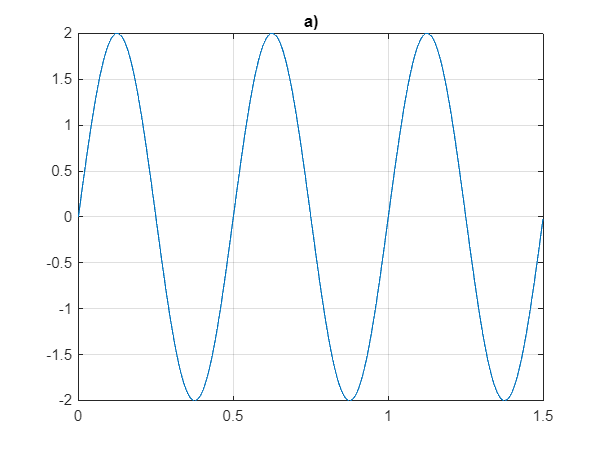


Ta=0.001; % Período de amostragem

% Sinal sinusoidal : x(t) = A * sin(2*pi*f*t + om) 
% A é a amplitude (valor máximo ou valor de pico) do sinal.
% f é a frequência em hertz (Hz).
% T é o período (o tempo que o sinal leva para completar um ciclo).
%
% om é a fase inicial em radianos.
%
% T = 1 / f

% a)

f_x = 2;
T= 1 / f_x;

t = 0:Ta:3*T-Ta; % Mostra 3 períodos e retira o último salto de Ta no fim

x = 2*sin(2*pi*2*t);
figure
plot(t,x)
title("a)")
grid on

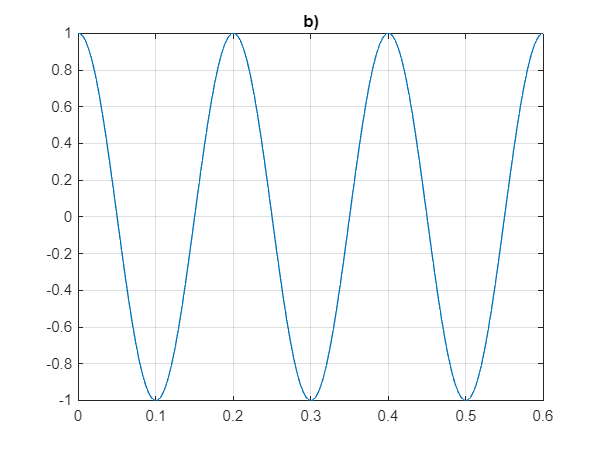


p_x = potencia(x,Ta,T);


% b)

fy = 5;
Ty = 1 / fy;

ty = 0:Ta:3*Ty-Ta;
y = sin(10*pi*ty+pi/2);

figure
plot(ty, y)
title('b)')
grid on

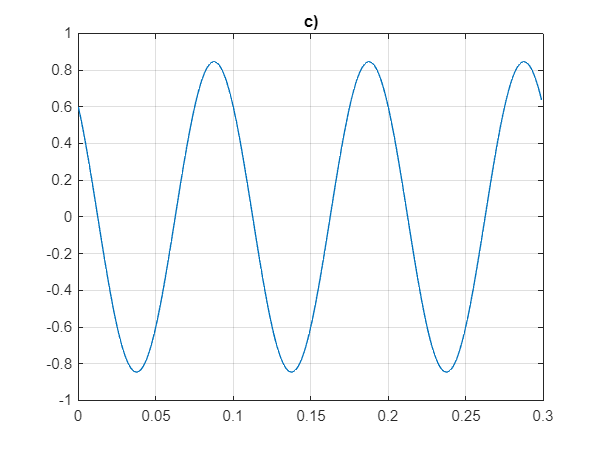


p_y = potencia(y,Ta,Ty);

% c)

fp = 10;
Tp = 1 / fp;

tp = 0:Ta:3*Tp-Ta;
p = sin(20*pi*tp+70*pi/180)+sin(20*pi*tp+200*pi/180);

figure
plot(tp,p)
title("c)")
grid on


p_p = potencia(p,Ta,Tp)

p_p = 0.3572

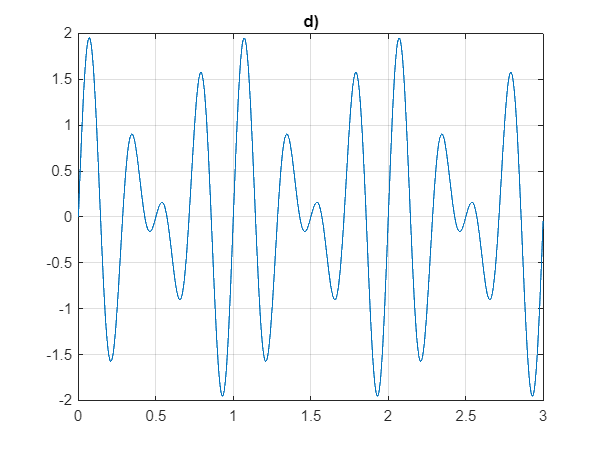


% d)

fz = gcd(3,4);     % para descobrir a frequência temos que fazer o max. divisor comum
Tz = 1 / fz;

tz = 0:Ta:3*Tz-Ta;
z = sin(6*pi*tz)+sin(8*pi*tz);

plot(tz,z)
title("d)")
grid on


pd = potencia(x,Ta,T)

pd = 2


% f) mesma coisa que o d) mas para descobrir a frequência:
% f1 = gcd(6,7);
% ff = gcd(f1,8);


## Exercício 2 - relação que determina o período de um sinal genérico

% A relação que determina o período de um sinal genérico é o 
% inverso do máximo divisor comum entre as frequências dos sinais. 


## Exercicio 3 - cálculo de potência

% Potências após cada sinal
% Função no fim e na pasta de funções


## Exercicio 4 - Variação de uma amplitude conforme valores de fi e f

Ta = 0.001;

N = 3 ;                 % número de sinais
A = [1,1,1];            % amplitude de cada sinal
fn = [10,20,30];         % frequencias de cada sinal, respetivamente

f1 = gcd(fn(1),fn(2)) ;    % mdc entre f_1 e f_2
f = gcd(f1, fn(3)) ;      % mdc entre f1 e f_3, ou seja, frequencia total

T = 1 / f;
t = 0:Ta:3*T;

% vetor de nums aleatorios entre -pi e pi
fi = rand(1,3)*2*pi-pi;  % multiplica se por 2pi para escalar os valores para [0,2pi]
                         % subtrai se por pi para deslocar o intervalo para
                         % [-pi,pi]                     
res = 0

res = 0


for i = 1:N
    res = res + A(i)*sin(2*pi*fn(i)*t+fi(i))
end

res =    -0.4967   -0.4413   -0.3840   -0.3253   -0.2653   -0.2042   -0.1424   -0.0799   -0.0172    0.0456    0.1083    0.1705    0.2320    0.2926    0.3521    0.4102    0.4666    0.5213    0.5738    0.6241    0.6719    0.7171    0.7595    0.7988    0.8350    0.8679    0.8974    0.9233    0.9456    0.9642    0.9789    0.9898    0.9968    0.9999    0.9990    0.9941    0.9854    0.9727    0.9562    0.9360    0.9120    0.8844    0.8534    0.8190    0.7813    0.7406    0.6970    0.6506    0.6016    0.5502


res =    -0.8037   -0.8651   -0.9180   -0.9611   -0.9928   -1.0120   -1.0176   -1.0089   -0.9852   -0.9462   -0.8917   -0.8219   -0.7371   -0.6379   -0.5252   -0.4001   -0.2638   -0.1178    0.0361    0.1964    0.3608    0.5276    0.6945    0.8594    1.0203    1.1749    1.3212    1.4573    1.5814    1.6917    1.7867    1.8651    1.9258    1.9679    1.9908    1.9941    1.9777    1.9418    1.8868    1.8133    1.7223    1.6149    1.4925    1.3566    1.2091    1.0517    0.8865    0.7155    0.5410    0.3650


res =    -0.2298   -0.4548   -0.6859   -0.9153   -1.1350   -1.3372   -1.5142   -1.6594   -1.7665   -1.8306   -1.8479   -1.8160   -1.7339   -1.6021   -1.4227   -1.1990   -0.9358   -0.6392   -0.3161    0.0258    0.3779    0.7317    1.0784    1.4096    1.7171    1.9938    2.2332    2.4300    2.5803    2.6815    2.7323    2.7330    2.6853    2.5921    2.4575    2.2869    2.0861    1.8620    1.6216    1.3722    1.1208    0.8744    0.6392    0.4207    0.2237    0.0518   -0.0925   -0.2078   -0.2941   -0.3522


pow = potencia(res,Ta,T)

pow = 1.5000

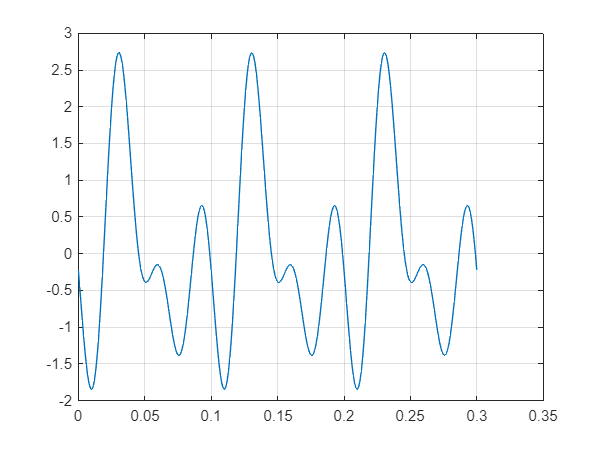


plot(t,res)
grid on

## Funções


function P = potencia(x,Ta,T)
    % Calcula, com base na fórmula da potência, a potência média de um
    % período
    % x - sinal sinusoidal
    % Ta - Passo
    % Periodo do sinal
    %
    % P - média da potência do sinal

    samples = T/Ta;     % Representa o número de samples num periodo do 
                        % sinal (50 neste caso)
    x = x(:,1:samples); % Extraimos todas as samples de x, que correspondem
                        % a um peíodo inteiro
    P = x*x'/samples;   % Soma os quadrados de todas as samples. Divide -se 
                        % pelo número de samples e devolve nas a média da 
                        % potencia em x
end